clear all; close all
A = [ 4 14 -12;
    0 -4 0;
    1.5 -1 -5];
B = [4; 0; 2];
J = [-1 1.2 3.4;
    -0.25 0.9 0.5;
    -0.85 0.8 2.4];
M = [0; 1; 1];
C = [0 1 0];

C = [C; C; C] %making square matrix out of C 

C =      0     1     0
     0     1     0
     0     1     0




%LMI variables
Pvar = sdpvar(3,3); %Lyapunov matrix
Zvar = sdpvar(3,3); %defining new indepenten matrices
Qvar = sdpvar(3,3);

ii = 100;           % maximal number of iteration steps
jj = 10; %max rough bisection steps

high = 100;
low = 1e-3;
Flow_stable = false

Flow_stable = logical
   0


%setting bounds based on expected stability of the solution
if Flow_stable %we have a minimal dwell time d < 0, c > 0
    % Loop parameters cvar
    lb_cvar = low;             % initial value lower search bound
    ub_cvar = high;            % initial value upper search bound
    
    % Loop parameters dvar
    lb_dvar = -high;             % initial value lower search bound
    ub_dvar= -low;            % initial value upper search bound
else %we have a maximal dwell time d > 0, c < 0
    lb_cvar = -high;             % initial value lower search bound
    ub_cvar = -low;            % initial value upper search bound
    
    % Loop parameters dvar
    lb_dvar = low;             % initial value lower search bound
    ub_dvar= high;            % initial value upper search bound
end

%checking bounds
if lb_cvar > ub_cvar %lower bound 
    display('bounds are ill defined')
    
elseif lb_dvar > ub_dvar
    display('bounds are ill defined')
end
%
d_cvar = 1e-8;      % maximal difference in cvar between to different iteration steps
d_dvar = 1e-8;      % maximal difference in dvar between to different iteration steps

% Set initial loop values
lbf_cvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
ubf_cvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

% Set initial loop values
lbf_dvar = NaN;      % lower bound feasible? NaN: not determined yet, 0: no, 1: yes
ubf_dvar = NaN;      % upper bound feasible? NaN: not determined yet, 0: no, 1: yes

%tracking variables
cvar_track = [];
dvar_track = [];

for i = 1:ii
    %Computing cvar and dvar using bisection
    cvar = bisection(lb_cvar,ub_cvar,lbf_cvar,ubf_cvar);
    dvar = bisection(lb_dvar,ub_dvar,lbf_dvar,ubf_dvar);

    %setting LMI conditions
    cond1 = A'* Pvar - Qvar' + Pvar*A - Qvar <= -cvar * Pvar;
    cond2 = [ exp(-dvar)*Pvar,  J'*Pvar - Zvar';
        Pvar*J - Zvar,     exp(dvar)*Pvar];

    %positive definite condition
    Lp = Pvar >= 1e-9;

    % combine constraints into one object
    L = [cond1, cond2, Lp];
    opts = sdpsettings('solver','sdpt3');
    diagnostics = optimize(L,[],opts); % solve the LMI problem

    % Check result
    % pres : Primal constraint residuals
    % dres : Dual constraint residuals
    [pres,~] = check(L);

    %checking feasiblity and changing bounds cvar or dvar  
    if mod(i,2) == 0
        [ub_cvar, lb_cvar, lbf_cvar, ubf_cvar] = CheckFeasibility(cvar,ub_cvar,lb_cvar,lbf_cvar,ubf_cvar,pres,diagnostics);
    else
        [ub_dvar, lb_dvar, lbf_dvar, ubf_dvar] = CheckFeasibility(dvar,ub_dvar,lb_dvar,lbf_dvar,ubf_dvar,pres,diagnostics);
    end


    
    %storing iteration
    cvar_track(i) = cvar;
    dvar_track(i) = dvar;

    if i>=4
         %check has minus two because the variable is changed every other cycle
        if abs(cvar-cvar_track(i-2)) < d_cvar
            if abs(dvar-dvar_track(i-2)) < d_dvar
                break;              % break loop if accurate enough
            end
        end
    end

    % Store feasible solution
    if min(pres) > 0 && diagnostics.problem == 0
        feasible.Pvar = Pvar;
        feasible.Qvar = Qvar;
        feasible.Zvar = Zvar;
        feasible.cvar = cvar;
        feasible.dvar = dvar;
    end

end


 num. of constraints = 18
 dim. of sdp    var  = 12,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.9e+03|2.7e+02|5.6e+03|-3.000000e-08  0.000000e+00| 0:0:00| chol  1  1 
 1|0.928|1.000|1.3e+02|1.0e-01|3.8e+02|-1.612900e-08  0.000000e+00| 0:0:00| chol  1  1 
 2|0.985|1.000|2.0e+00|1.0e-02|5.5e+00|-2.227455e-10  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|2.2e-02|1.0e-03|6.2e-02|-2.504424e-12  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|2.4e-04|4.5e-03|6.9e-04|-2.758396e-14  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|2.7e-06|5.8e-05|7.6e-06|-3.062295e-16  0.000000e+00| 0:

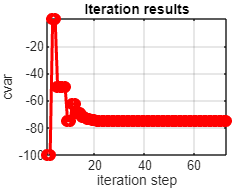


% Plot iteration history
figure(1)
tiledlayout(1,2)
plot(cvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('cvar')
title('Iteration results')
grid on
axis tight

nexttile

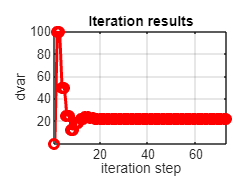

plot(dvar_track,'ro-','LineWidth',2)
xlabel('iteration step')
ylabel('dvar')
title('Iteration results')
grid on
axis tight


% Retrieve output
P = value(feasible.Pvar)

P =     1.1575   -0.1219   -0.4312
   -0.1219    1.7166    0.0612
   -0.4312    0.0612    1.7941


Q = value(feasible.Qvar)

Q = 1.0e+08 *

    1.3806   -0.0000    0.0000
   -0.0000    1.3806    0.0000
    0.0000    0.0000    1.3806


Z = value(feasible.Zvar)

Z =    -1.4290    0.4869    1.3241
    0.4869    1.5009    0.9689
    1.3241    0.9689    3.4855



L1  = inv(P) * Q  %L1 times C

L1 = 1.0e+08 *

    1.3184    0.0824    0.3141
    0.0824    0.8104   -0.0078
    0.3141   -0.0078    0.8453


L2 = J - inv(P)* Z  %L2 times C

L2 =     0.0343    0.4250    1.2848
   -0.4429   -0.0046   -0.1280
   -1.3328    0.1046   -0.0297



c = value(feasible.cvar)

c = -74.9996

d = value(feasible.dvar)

d = 21.8758



dwelltime = abs(d)/abs(c)

dwelltime = 0.2917